+% Load the dataset
data = readtable("C:\Users\hp\OneDrive\Desktop\AirQualityUCI.xlsx");


% Check for missing values and clean if necessary
if any(any(ismissing(data)))
    disp('Data contains missing values. Cleaning data...');
    data = rmmissing(data);
end
disp("Air Quality Analysis: A Data-Driven Approach Using Singular Value Decomposition");

Air Quality Analysis: A Data-Driven Approach Using Singular Value Decomposition



% Select only the numerical columns (excluding Date and Time)
numericData = data{:, 3:end}; % Columns from the 3rd onward

% Perform SVD on the numerical data
[U, S, V] = svd(numericData, 'econ');

% Display U, S, and V matrices
disp('Matrix U:');

Matrix U:


disp(U);

    0.0123   -0.0022   -0.0018    0.0039    0.0233    0.0055    0.0088    0.0034    0.0063    0.0002   -0.0063    0.0128    0.0082
    0.0113   -0.0080   -0.0034    0.0009    0.0213   -0.0059    0.0099    0.0026    0.0060    0.0021   -0.0045    0.0145    0.0063
    0.0116   -0.0061   -0.0049    0.0042    0.0205   -0.0067    0.0157    0.0131    0.0041   -0.0006   -0.0083    0.0180    0.0023
    0.0118   -0.0037   -0.0051    0.0056    0.0195    0.0028    0.0127    0.0122    0.0029   -0.0015   -0.0051    0.0141    0.0030
    0.0112   -0.0073   -0.0073    0.0065    0.0181    0.0090    0.0104    0.0125    0.0030   -0.0025   -0.0064    0.0135    0.0006
    0.0105   -0.0119   -0.0094    0.0062    0.0177    0.0079    0.0097    0.0104    0.0025   -0.0008   -0.0067    0.0137   -0.0042
    0.0100   -0.0167   -0.0111    0.0030    0.0180   -0.0011    0.0129    0.0100   -0.0003    0.0020   -0.0094    0.0188   -0.0071
    0.0099   -0.0167   -0.0108    0.0023    0.0177    0.0028    0.0108    0.0086   

disp('Matrix S:');

Matrix S:


disp(S);

   1.0e+05 *

    2.3681         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.4413         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.2559         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.1696         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1474         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.0850         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0759         0         0         0         0         0         0
         0         0         0         0         0         0         

disp('Matrix V:');

Matrix V:


disp(V);

   -0.0133    0.0510   -0.1288   -0.1412    0.1526   -0.0041   -0.3587    0.4137    0.3053    0.7378   -0.0003    0.0001    0.0003
    0.4477    0.0376   -0.1169    0.1943    0.0924   -0.5619    0.4621    0.4420   -0.0926    0.0150   -0.0677    0.0140   -0.0019
   -0.0597    0.0606    0.1287    0.0093    0.9551    0.0523    0.1448   -0.1992   -0.0083    0.0073    0.0103   -0.0160   -0.0004
    0.0050    0.0042    0.0297    0.0669    0.0815   -0.1096   -0.3512    0.0742   -0.2852   -0.0940   -0.1923    0.6688   -0.5222
    0.3887    0.1797    0.0670   -0.0055   -0.0382   -0.5015   -0.3416   -0.5846    0.2944    0.0503    0.1030   -0.0291    0.0092
    0.0728    0.3634   -0.6384   -0.4377   -0.0005    0.0552    0.1141   -0.2285   -0.4176    0.1377   -0.0418   -0.0042    0.0036
    0.3151   -0.7730   -0.4621    0.1400    0.1020    0.1592   -0.0899   -0.1579    0.0314    0.0169   -0.0109    0.0040   -0.0020
    0.0244    0.1202   -0.3132   -0.3136    0.1471   -0.0050   -0.2056    0.3270   

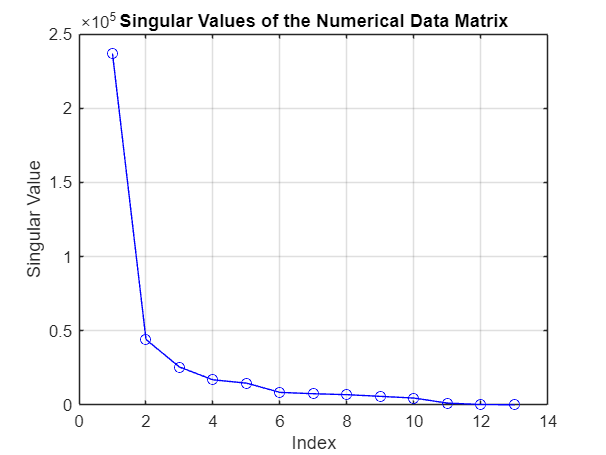


% Plot singular values
figure;
singular_values = diag(S);
plot(singular_values, 'bo-');
title('Singular Values of the Numerical Data Matrix');
xlabel('Index');
ylabel('Singular Value');
grid on;

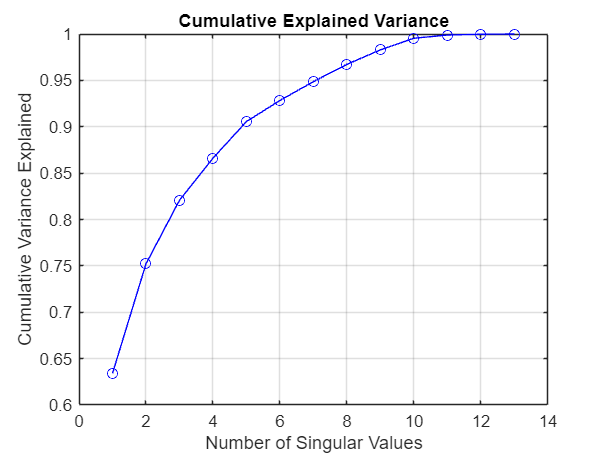


% Cumulative variance explained
explained_variance = cumsum(singular_values) / sum(singular_values);
figure;
plot(explained_variance, 'bo-');
title('Cumulative Explained Variance');
xlabel('Number of Singular Values');
ylabel('Cumulative Variance Explained');
grid on;

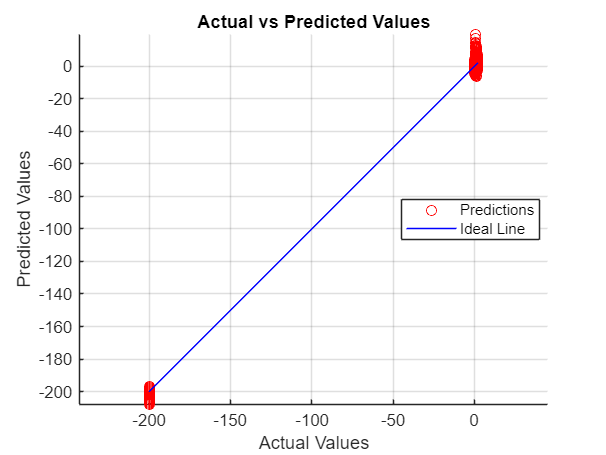


% Use SVD to reduce dimensionality
k = 10;  % Choose number of singular values (dimensions)
numericData_reduced = U(:, 1:k) * S(1:k, 1:k);

% Assuming the dataset lacks a target variable; otherwise, replace y with an appropriate target
y = numericData(:, end); % Here, we assume the last column as the target variable (example setup)

% Fit a linear regression model on reduced data
model = fitlm(numericData_reduced, y);

% Make predictions
predictions = predict(model, numericData_reduced);

% Display predicted output (uncomment if needed)
% disp('Predicted Outputs:');
% disp(predictions);

% Plot actual vs predicted values
figure;
scatter(y, predictions, 'ro');
hold on;
plot(y, y, 'b-');  % Ideal line where predicted = actual
title('Actual vs Predicted Values');
xlabel('Actual Values');
ylabel('Predicted Values');
grid on;
legend('Predictions', 'Ideal Line', 'Location', 'Best');
axis equal;  % Make the axes equal


% Calculate evaluation metrics (uncomment if needed)
% MAE = mean(abs(predictions - y));
% R_squared = 1 - sum((predictions - y).^2) / sum((y - mean(y)).^2);

% Display evaluation metrics (uncomment if needed)
% disp(['Mean Absolute Error: ', num2str(MAE)]);
% disp(['R-squared: ', num2str(R_squared)]);

% Optionally calculate accuracy based on a threshold (uncomment if needed)
% threshold = 0.1; % Define a threshold for accuracy
% predicted_labels = abs(predictions - y) < threshold; % Boolean array
% accuracy = sum(predicted_labels) / length(y); % Proportion of correct predictions
% disp(['Accuracy (within threshold): ', num2str(accuracy * 100), '%']);
